Fs = 1e4;%サンプル周波数
fs = 1e4;
t = 0:1/Fs:1;
%加速度センサの感度
Vg_Chest = 0.66;
Vg_NeckSkin = 0.2;
Vg_NeckStrap = 0.2;
vg = 0.2;

FolderNum = 10;
AllData = cell(FolderNum,1);
nharm = 6;%thdの高調波数

%10列2行のセルを作成。1列目にy軸加速度の行列、2列目に力センサ
%（できれば1-の連番にして一々ファイル名を変更しないでも良いようにしたい

list = dir('*.csv');
numFiles = length(list);
Mx = cell(numFiles,2);    
Fx = cell(numFiles,2);  
G = cell(numFiles,2);
F = zeros(fs,numFiles);


    for i = 1:numFiles
      Mx{i,1}= csvread(list(i).name,21,1,[21,1,10020,4]);
%各列の平均値を差し引く
%          for k = 1:10000
%         Mx{i,2}(k,1) = k / fs;
% %         Mx{i,2}(k,2) = sqrt((Mx{i,1}(k,1)^2 + Mx{i,1}(k,2)^2 + Mx{i,1}(k,3)^2)/3) / vg;
%         Mx{i,2}(k,3) = Mx{i,1}(k,4);
%         end
%      xyz = xyz - mean(xyz);
     x = ( Mx{i,1}(:,1) - mean(Mx{i,1}(:,1)) ) / vg;
     y = ( Mx{i,1}(:,2) - mean(Mx{i,1}(:,2)) ) / vg;
     z = ( Mx{i,1}(:,3) - mean(Mx{i,1}(:,3)) ) / vg;   
     xyz = x + y + z;
     Vin = 2*sqrt(2)*rms(Mx{i,1}(:,4));
%3軸加速度を加算したものを記録
     Mx{i,2} = xyz;
%入力電圧の周波数を取得し記録（harmfreq)
     [thd_db,harmpow,harmfreq] = thd(Mx{i,1}(:,4),Fs,nharm);
     Mx{i,3} = harmfreq(1,1);
  
   %   各列を2回積分して変位に
    temp = 1/fs * cumtrapz(xyz);
    temp = temp - mean(temp);
    XYZ = 1/fs * cumtrapz(temp) * 9.80665 * 1e6;
    
    F(:,i) = XYZ;
    
    end
  

TT = timetable(F,'SampleRate',Fs);
 % パラメーター
timeLimits = seconds([0 0.9999]); % 秒
frequencyLimits = [0 1000]; % Hz


    for i = 1:numFiles
        TT_F_X_ROI = TT.F(:,i);
        timeValues = TT.Properties.RowTimes;
        TT_F_X_ROI = timetable(timeValues,TT_F_X_ROI,'VariableNames',{'Data'});
        TT_F_X_ROI = TT_F_X_ROI(timerange(timeLimits(1),timeLimits(2),'closed'),1);
        [PTT_F_X_ROI, FTT_F_X_ROI] = pspectrum(TT_F_X_ROI,'FrequencyLimits',frequencyLimits);
        Fx{i,1} = TT_F_X_ROI;
        Fx{i,2} = PTT_F_X_ROI;
        Fx{i,3} = FTT_F_X_ROI;
        %探索用周波数の記録
        Fx{i,4} = Mx{i,3};
        graphdata(i,1) = Fx{i,4};
        [M I] = min(abs(Fx{i,3}-Fx {i,4}));
        Fx{i,5} = mag2db(Fx{i,2}(I,1))/2;
        graphdata(i,2) = Fx{i,5};
    end

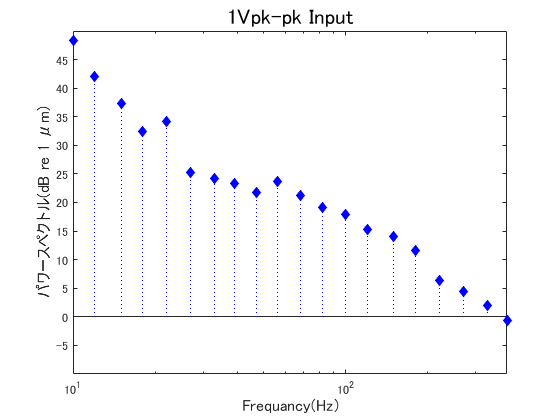

Voltage = num2str(round(Vin));
VoltageTitle = strcat(Voltage,'Vpk-pk Input');
    
stem(graphdata(:,1),graphdata(:,2),'filled','LineStyle',':','Color','b','Marker','diamond'); 

% legend('Chest','Neck Skin','Neck Strap','Position',[0.47 0.75 0.1 0.15],'fontsize',12);
 set(gca,'xscale','log');    %x軸をlogscaleに
 xlabel('Frequancy(Hz)','fontsize',12);
 ylabel('パワースペクトル(dB re 1 μm)','fontsize',12);
 title(VoltageTitle, 'fontsize',16)


%     [row,col] = find(___)
% min(abs(data-));
    
%      [XYZ_thd_db,XYZ_harmpow,XYZ( Mx{i,1}(:,1) - mean(Mx{i,1}(:,1)) ) / vg;_harmfreq] = thd(XYZ,Fs,nharm); 
%        
%        
%         [x_thd_db,x_harmpow,x_harmfreq] = thd(Mx{i,1}(:,1),Fs,nharm); 
%         [NeckSkin_thd_db,NeckSkin_harmpow,NeckSkin_harmfreq] = thd(Mx{i,1}(:,2),Fs,nharm);
%         [NeckStrap_thd_db,NeckStrap_harmpow,NeckStrap_harmfreq] = thd(Mx{i,1}(:,3),Fs,nharm);
%         [Input_thd_db,Input_harmpow,Input_harmfreq] = thd(Mx{i,1}(:,4),Fs,nharm);
%             Mx{i,2}(:,1) = x_thd_db;
%             Mx{i,2}(:,2) = NeckSkin_thd_db;
%             Mx{i,2}(:,3) = NeckStrap_thd_db;
%             Mx{i,2}(:,4) = Input_thd_db;
%             Mx{i,3}(:,1) = x_harmpow;
%             Mx{i,3}(:,2) = NeckSkin_harmpow;
%             Mx{i,3}(:,3) = NeckStrap_harmpow;
%             Mx{i,3}(:,4) = Input_harmpow;
%             Mx{i,4}(:,1) = x_harmfreq;
%             Mx{i,4}(:,2) = NeckSkin_harmfreq;
%             Mx{i,4}(:,3) = NeckStrap_harmfreq;
%             Mx{i,4}(:,4) = Input_harmfreq;
%             Mx{i,5}(:,1) = 100*(10^(x_thd_db/20));
%             Mx{i,5}(:,2) = 100*(10^(NeckSkin_thd_db/20));
%             Mx{i,5}(:,3) = 100*(10^(NeckStrap_thd_db/20));        
%             Mx{i,5}(:,4) = 100*(10^(Input_thd_db/20));
%             
%         %各RMS値計算
%         Mx{i,6}(:,1) = rms(Mx{i,1}(:,1)) / Vg_Chest;
%         Mx{i,6}(:,2) = rms(Mx{i,1}(:,2)) / Vg_NeckSkin;        
%         Mx{i,6}(:,3) = rms(Mx{i,1}(:,3)) / Vg_NeckStrap;
%         Mx{i,6}(:,4) = 2*sqrt(2)*rms(Mx{i,1}(:,4));
%         
%         %グラフ用のセルに整頓
%         G{i,1} = Mx{i,6}(:,4);%入力信号のRMS
%         %THD
%         G{i,2}(:,1) = Mx{i,5}(:,1);
%         G{i,2}(:,2) = Mx{i,5}(:,2);
%         G{i,2}(:,3) = Mx{i,5}(:,3);
%         G{i,2}(:,4) = Mx{i,5}(:,4);
%         %RMS
%         G{i,3}(:,1) = Mx{i,6}(:,1);
%         G{i,3}(:,2) = Mx{i,6}(:,2);
%         G{i,3}(:,3) = Mx{i,6}(:,3);
      
%         AllData{k,1} = DataName;
%         AllData{k,2} = Mx;
%     end

% Frequency = num2str(round(Mx{1,4}(1,4))); %周波数を文字列表示
% GraphTitleTHD = strcat(Frequency,'Hz THD+N');
% GraphTitleRMS = strcat(Frequency,'Hz Acceralation');
% 
% graphdata = cell2mat(G);
% 
% stem(graphdata(:,1),graphdata(:,2),'filled','LineStyle',':','Color','y','Marker','o'); %加速度グラフ
% hold on
% stem(graphdata(:,1),graphdata(:,3),'filled','LineStyle',':','Color','b','Marker','diamond'); %張力のグラフ 
% stem(graphdata(:,1),graphdata(:,4),'filled','LineStyle',':','Color','m','Marker','square');  %入力電圧
% stem(graphdata(:,1),graphdata(:,5),'filled','LineStyle',':','Color','g','Marker','square');  %入力電圧
% legend('Chest','Neck Skin','Neck Strap','Input V','Position',[0.47 0.75 0.1 0.15],'fontsize',12);
% % set(gca,'xscale','log');    %x軸をlogscaleに
% xlabel('Input Voltage(V)','fontsize',12);
% ylabel('THD+N(%)','fontsize',12);
% ylim([0 200]);
% title(GraphTitleTHD, 'fontsize',16)
% hold off
% 
% stem(graphdata(:,1),graphdata(:,6),'filled','LineStyle',':','Color','y','Marker','o'); %加速度グラフ
% hold on
% stem(graphdata(:,1),graphdata(:,7),'filled','LineStyle',':','Color','b','Marker','diamond'); %張力のグラフ 
% stem(graphdata(:,1),graphdata(:,8),'filled','LineStyle',':','Color','m','Marker','square');  %入力電圧
% legend('Chest','Neck Skin','Neck Strap','Position',[0.47 0.75 0.1 0.15],'fontsize',12);
% % set(gca,'xscale','log');    %x軸をlogscaleに
% xlabel('Input Voltage(V)','fontsize',12);
% ylabel('Acceralation(G)','fontsize',12);
% ylim([0 6]);
% title(GraphTitleRMS, 'fontsize',16)
% hold off

% for k =1 : FolderNum
%     switch k
%         case 1
%             cd 10\
%             DataName = '10Hz';
%         case 2
%             cd 15\
%             DataName = '15Hz';            
%         case 3
%             cd 22\
%             DataName = '20Hz';
%         case 4
%             cd 33\
%             DataName = '33Hz';
%         case 5
%             cd 47\
%             DataName = '47Hz';
%         case 6
%             cd 68\
%             DataName = '68Hz';
%         case 7
%             cd 100\
%             DataName = '10Hz';
%         case 8
%             cd 150\
%             DataName = '100Hz';
%         case 9
%             cd 220\
%             DataName = '220Hz';
%         case 10
%             cd 330\
%             DataName = '330Hz';
%     end
% cd ..
% end


